Plotting the derivative of lhet with respect to t and lhet to analyze validity

[x,lhet] = meshgrid(logspace(-7,-1), linspace(0,500));
dlhetdt = @(x,lhet) (1000 - lhet).*(x.*(x+1).*(x-3));

Flowing func generated by seperation of variabhles followed by integration of both sides

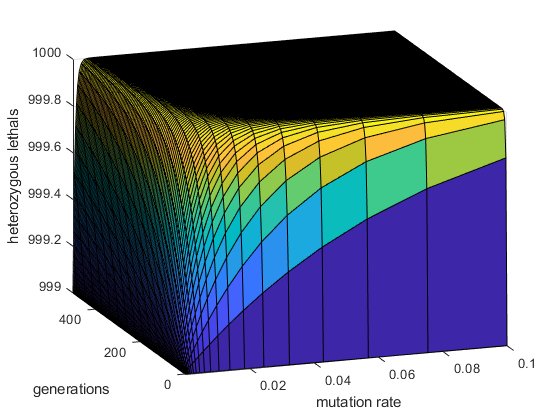

[x,t] = meshgrid(logspace(-7,-1), linspace(0,500));
lhet = @(x,t) 1000 - exp(x.*(x+1).*(x-3).*t);

figure
surfc(x, t, lhet(x,t))
xlabel("mutation rate")
ylabel("generations")
zlabel("heterozygous lethals")
grid on